## 图像说明

% 浅绿色 = X 
% 深绿色 = X⊖ε
% 蓝色   = control invariant set

## 创建系统

clc; clear; close all;

%% 单位设定
    TRUE = 1;
    FALSE = 0;
    km_h = 1/3.6;

%% 1.创建系统
    A = [1.0000    0.0999;
          0    0.9976];

    B = [0.0083;
         0.1665];

## 测试

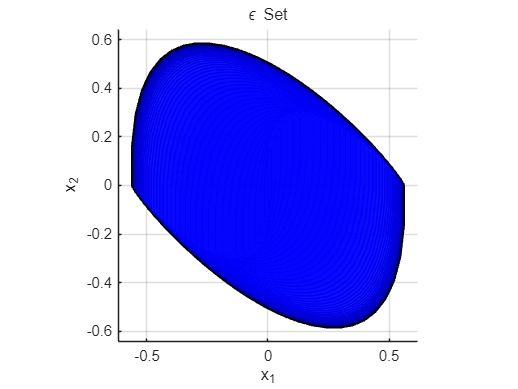

在第 49 次迭代时收敛。


Q_e = diag([1,0.8]);
R_e = 1;
Q_f = eye(size(A));
R_f = 50;

u_tilde = [-0.5, +0.5]; 

% 数据范围
X_safe = [10;0];     % 安全值
X = [6      inf;        % delta_x
    -inf   +inf];       % delta_V

X(:,1) = X(:,1) - X_safe;
X(:,2) = X(:,2) - X_safe;


W = (B * u_tilde) ; % 创建 扰动范围
W = sort(W,2)     ; % 行元素从小到大排
% W = [-0.1 +0.1;
%      -0.1 +0.1];


% 创建 Polyhedron 数据
X = Polyhedron('lb',[X(1,1);X(2,1)],...  % delta_x = x_tilde - x - x_safe
               'ub',[X(1,2);X(2,2)]);    % delta_V = v_tilde - v - 0
U = Polyhedron('lb',-1,...
               'ub',+1);
W = Polyhedron('lb',[W(1,1);W(2,1)], ...
               'ub',[W(1,2);W(2,2)]);



% 计算 ε set
[E, K_e] = plot_EpsilonSet(A,-B,  ...
                           Q_e, R_e,  ...
                           W, 80, ...
                           TRUE);

% 计算 XT UT 约束收紧
[XT, UT] = plot_Tighten(X, U, ...
                        E, K_e, ...
                        FALSE);

X_tilde:
 x1 in [-3.44, Inf]
 x2 in [-Inf, Inf]
U_tilde:
 [-0.33, 0.33]


% 计算 X_f 
Xf = plot_InvariantSets(A,B, ...
                        Q_f,R_f, ...
                        XT,UT, ...
                        FALSE);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...


Kf = dlqr(A,-B,Q_f,R_f);

KE = K_e * E;

% 需要保存内容
%   XT 状态约束 (收紧)
%   UT 输入约束 (收紧)
%   Xf 终止集
%   Qf 终端 用于计算 Vf 中的 P
%   Rf 终端

fprintf('Finish')

Finish

## 画图

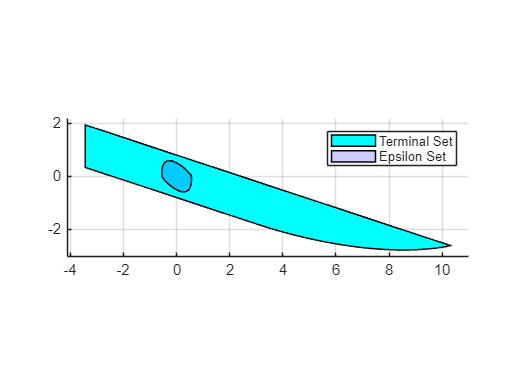

figure; grid on; hold on; axis equal;
% X.plot('color','g','alpha',0.4);
% XT.plot('color','g','alpha',0.4);   
Xf.plot('color','c');
E.plot('color','b','alpha',0.2);
legend('Terminal Set','Epsilon Set')
hold off


XT.contains([0;0])

ans = logical
   1



% figure; grid on; hold on; axis equal;
% U.plot('color','g','alpha',0.4);
% UT.plot('color','red','alpha',0.4);   
% hold off

## 代码简化 LTISystem

% 先前参数
close all; clear; clc;

A = [1 0.0999;
     0 0.9976];
B = -[0.0083;
      0.1665];


Q_e = diag([1,0.8]);
R_e = 0.1;

Q_MPC = diag([1,0.8]);
R_MPC = 0.1;

Q_f = eye(size(A));
R_f = 50;

% 创建系统
sys = LTISystem('A',A,'B',B);

% 计算 Terminal Set
sys.x.min = [-1; -1];      sys.x.max = [+1; +1];
sys.u.min = [-1];          sys.u.max = [+1];
sys.x.penalty = QuadFunction(Q_f);
sys.u.penalty = QuadFunction(R_f);
Xf = sys.LQRSet;                     % 打印日志关闭不了

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...




help LTISystem

  Object representation of an LTI system
 
  To create an LTI object out of a state-space object:
    s = LTISystem(ss)
 
  To import data from sysStruct/probStruct:
    s = LTISystem(sysStruct, probStruct)

    LTISystem 的文档





% Xf.plot


% % 系统设置
% sys.x.min = []; sys.x.max = [];
% sys.u.min = []; sys.u.max = [];
% sys.x.penalty = QuadFunction(Q);
% sys.u.penalty = QuadFunction(R);
% sys.x.with('terminalPenalty');
% sys.x.terminalPenalty = QuadFunction(P_t);
% sys.x.with('terminalSet');
% sys.x.terminalSet = Xf;